init = [1570 692 28 411 0 351 3033 662 265 0 295 0];
edge_remove_origin = [2785 761 56 455 0 832 5281 1856 689 0 439 0];
edge_remove_test = [1757 692 28 411 0 423 3407 893 308 0 338 0];
rotation = [6900 1178 76  2969 48  4677 13755 5866 1567 15 9016 115];

edge_remove_origin_calibrate = edge_remove_origin - init;
edge_remove_test_calibrate = edge_remove_test - init;
rotation_calibrated = rotation - init;

name = {'edge - face' 'edge - nodes' 'edge - tet'  'face - edge' 'face - node'...
    'face - tet' 'node - edge' 'node - face' 'node - tet' 'tet - edge' ...
    'tet - face' 'tet - node'};

disp('Edge removal references (include cross reference)');

Edge removal references (include cross reference)


t = table(name', edge_remove_origin_calibrate', edge_remove_test_calibrate', ...
    rotation_calibrated', ...
        'VariableNames', {'name' 'origin', 'test', 'rotation'});
display(t);

t =          name         origin    test    rotation
    ______________    ______    ____    ________
    'edge - face'     1215      187      5330   
    'edge - nodes'      69        0       486   
    'edge - tet'        28        0        48   
    'face - edge'       44        0      2558   
    'face - node'        0        0        48   
    'face - tet'       481       72      4326   
    'node - edge'     2248      374     10722   
    'node - face'     1194      231      5204   
    'node - tet'       424       43      1302   
    'tet - edge'         0        0        15   
    'tet - face'       144       43      8721   
    'tet - node'         0        0       115   

% Calibrate rotation
a = rotation_calibrated;
a(8) = a(8) - 2*a(9);

a(1) = a(1) - a(8); a(7) = a(7) - a(8);
a(6) = a(6) - a(9); 
a(6) = a(6) - 3*a(3); a(1) = a(1) - 3*a(3);
a(2) = a(2) - a(5); a(4) = a(4) - 14*a(5);
a(2) = a(2) - a(12); a(4) = a(4) - 14*a(12); a(11) = a(11) - 70*a(12);
a(4) = a(4) - a(10); a(11) = a(11) - 5*a(10);

disp('Rotation references');

Rotation references


index = 1:12;
t2 = table(index', name', a', rotation_calibrated', rotation', ...
    'VariableNames', {'i', 'name', 'true', 'calibrated', 'measured'});
display(t2);

t2 =     i          name         true    calibrated    measured
    __    ______________    ____    __________    ________
     1    'edge - face'     2586     5330          6900   
     2    'edge - nodes'     323      486          1178   
     3    'edge - tet'        48       48            76   
     4    'face - edge'      261     2558          2969   
     5    'face - node'       48       48            48   
     6    'face - tet'      2880     4326          4677   
     7    'node - edge'     8122    10722         13755   
     8    'node - face'     2600     5204          5866   
     9    'node - tet'      1302     1302          1567   
    10    'tet - edge'        15       15            15   
    11    'tet - face'       596     8721          9016   
    12    'tet - node'       115      115           115   

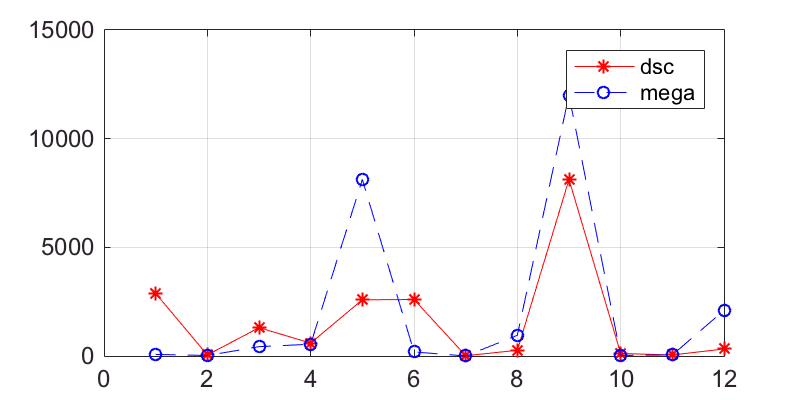

% Map to their paper
map = [5 12 2 8 11 1 9 6 3 7 4 10];
map1 = [6 3 9 11 1 8 10 4 7 12 5 2];

name_ref = {'F(R)'; 'E(R)'; 'V(R)'; 'R(F)'; 'E(F)'; ...
    'V(F)'; 'R(E)'; 'F(E)'; 'V(E)'; 'R(V)'; 'F(V)'; 'E(V)'};
mega_ref = [73 23 429 543 8121 185 1 950 12006 27 48 2102]';

b = a(map1);

hhf = figure;
plot(b, 'r*-');
hold on;
plot(mega_ref, 'bo--');
ax = gca;ax.XTickLabel = name_ref;tt=1:12; ax.XTick=tt;
legend('dsc', 'mega');
set(hhf, 'Position', [100, 100, 400, 200]); grid on;